# ModelB SM with dampening integrator Model

Model B to Single Machine Model, to model a weak grid with finite inertia. Based on Gomez's eqs 10.3-10.7 for both machines, grid is motoring, grid swing eq (5) may have additional damping term commented out. CURRENTLY NO DISTURBANCE/STEP-CHANGE, TBC.

### **Constants**

f  = 50;
ws = 2*pi*f;  %chosen reference rotational velocity, rad/s

% Machine 1 Network (Keep this part)
Xd1 = 0.1;
XT1 = 0.05;
X1 = Xd1 + XT1;

% Model B / Inverter Parameters (Replaces Machine 1 physics)
Pref_init = 1.0;

H_equiv = 3;
J = 2*H_equiv / (ws^2);
Dp = 0.1;
nq = 0.05;
Kiq = 1;

% Base values for Machine 2 (Since we deleted D1 and H1)
D1_base = 0.1; 
H1_base = 3;

% Machine 2 / finite grid
D2 = 4*D1_base;
H2 = 4*H1_base;

% AEMO 3.2.11 Test 168 grid strength

SCR = 3;

Xs = 1/SCR;

% Preserve original XL:X2 ratio of 3:1

XL = 0.75*Xs;

X2 = 0.25*Xs;

XTot = X1 + XL + X2;


% Grid-side load integrator

Ki_grid = 0.05;

Pload0 = Pref_init;

Pm2_initial = -Pload0;



### Design Parameters

% K1 = 1.2;  %Gen Gain Constant
% K2 = 4*K1; %Grid Gain Constant

### Specified Inputs

% Specified Inputs
K2 = 4*1.2;          % Grid Gain Constant
V2o = 1;

%Comment out below to disable fault
V1o = 1;

% AEMO 3.2.11 Test 168 event times

Pref_t1 = 5;
Pref_t2 = 15;
Pref_t3 = 25;

% AEMO Figure 5 active power reference

Pref_step = @(t) 1.00.*(t < Pref_t1) + 0.50.*(t >= Pref_t1 & t < Pref_t2) + 0.05.*(t >= Pref_t2 & t < Pref_t3) + 1.00.*(t >= Pref_t3);

% % Check that a power-flow solution exists
% s1 = Pm*XL/(Vinf*V1o);
% s2 = Pm*XL/(Vinf*V1o_after);
% if abs(s1) > 1 && abs(s2) >1
%     error('No steady-state equilibrium exists for this Pm and V1o.');
% end

### Initial Conditions

% The following are for initial conditions at a steady state equilibrium
domega10 = 0;

domega20 = 0;

V2PCCmag0 = V2o;

delta2PCC0 = 0;

% AEMO Test 168 initial operating point
% P = 1 pu
% Q = 0 pu

arg = 2*Pref_init*XL/(V2PCCmag0^2);

if abs(arg) > 1
    error('No P = 1 pu, Q = 0 pu equilibrium exists for the selected grid strength.');
end

delta1PCC0 = 0.5*asin(arg);

V1PCCmag0 = V2PCCmag0*cos(delta1PCC0);

Q12 = 0;

Q21 = (V2PCCmag0^2 - V2PCCmag0*V1PCCmag0*cos(delta2PCC0-delta1PCC0))/XL;

Qref = 0;

E10 = hypot(Pref_init*X1/V1PCCmag0, V1PCCmag0 + Q12*X1/V1PCCmag0);
delta10 = delta1PCC0 + atan2(Pref_init*X1/V1PCCmag0, V1PCCmag0 + Q12*X1/V1PCCmag0);
E20 = hypot(Pm2_initial*X2/V2PCCmag0, ...
    V2PCCmag0 + Q21*X2/V2PCCmag0);

delta20 = delta2PCC0 + atan2(Pm2_initial*X2/V2PCCmag0, ...
    V2PCCmag0 + Q21*X2/V2PCCmag0);

% State 3 is now the RPC Integrator state, initialized to steady state
x3_0 = E10 - V1o;

x0 = [delta10;
      domega10;
      x3_0;
      delta20;
      domega20;
      E20;
      Pload0;
      V1PCCmag0;
      delta1PCC0;
      V2PCCmag0;
      delta2PCC0];

% Helper functions for local PCC power and dynamic E1
Ppcc = @(x) (x(8)*x(10)/XL)*sin(x(9)-x(11));

Qpcc = @(x) (x(8)^2 - x(8)*x(10)*cos(x(9)-x(11)))/XL;

Pe2 = @(x) (x(6)*x(10)/X2)*sin(x(4)-x(11));

E1 = @(x) V1o + nq*(Qref - Qpcc(x)) + x(3);

### State Space Equations and Solve

DynamicsEqs = @(t,x)[

    x(2);

    (1/(J*ws))*(Pref_step(t) - Ppcc(x) - Dp*x(2));

    Kiq*(Qref - Qpcc(x));

    x(5);

    (ws/(2*H2))*(-x(7) - Pe2(x) - D2*x(5));

    K2*(V2o - x(10));

    Ki_grid*x(5);

    (E1(x)*x(8)/X1)*sin(x(1)-x(9)) - Ppcc(x);

    (E1(x)*x(8)*cos(x(1)-x(9)) - x(8)^2)/X1 - Qpcc(x);

    (x(6)*x(10)/X2)*sin(x(4)-x(11)) - (x(10)*x(8)/XL)*sin(x(11)-x(9));

    (x(6)*x(10)*cos(x(4)-x(11)) - x(10)^2)/X2 - (x(10)^2 - x(10)*x(8)*cos(x(11)-x(9)))/XL
];

Mass = diag([1 1 1 1 1 1 1 0 0 0 0]);
options = odeset('Mass',Mass,'MaxStep',0.01,'RelTol',1e-7,'AbsTol',1e-9);

tspan = [0 35];

[t,x] = ode15s(DynamicsEqs,tspan,x0,options);

### Calculating PG and QG at each point in time

% Use x vector to get P, Q
delta1  = x(:,1);
domega1 = x(:,2);
x3      = x(:,3);

delta2  = x(:,4);
domega2 = x(:,5);
E2      = x(:,6);

Pload   = x(:,7);

V1PCCmag  = x(:,8);
delta1PCC = x(:,9);

V2PCCmag  = x(:,10);
delta2PCC = x(:,11);

PG      = zeros(length(t),1);
QG      = zeros(length(t),1);

for n = 1:length(t)
    
    PG(n) = (V1PCCmag(n)*V2PCCmag(n)/XL)*sin(delta1PCC(n)-delta2PCC(n)); % Active power from PCC1 to PCC2

    QG(n) = (V1PCCmag(n)^2/XL) - (V1PCCmag(n)*V2PCCmag(n)/XL)*cos(delta1PCC(n)-delta2PCC(n)); %Reactive power from PCC1 to PCC2
end

### Plot -WHICH PLOTS WE WANT TBC

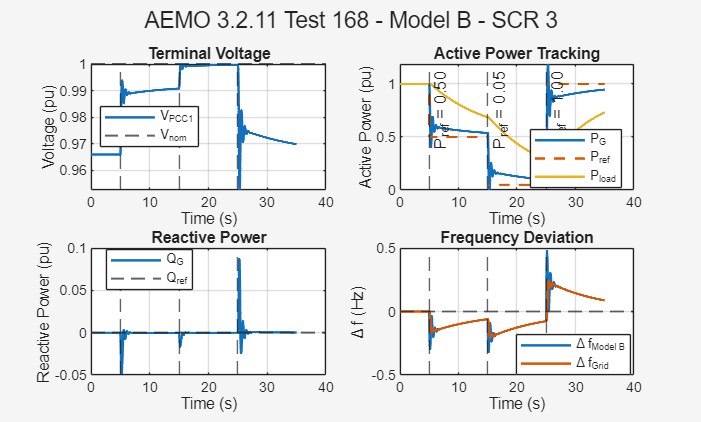

%% Plot Results

% Generate AEMO Pref command over simulation time
Pref_plot = Pref_step(t);


%% ============================================================
% MAIN AEMO 3.2.11 RESULTS
% ============================================================

figure('Visible','on');


%% 1. Terminal Voltage

subplot(2,2,1);

plot(t,V1PCCmag,'LineWidth',1.5);
hold on;

yline(V1o,'--','LineWidth',1.2);

xline(Pref_t1,'--');
xline(Pref_t2,'--');
xline(Pref_t3,'--');

xlabel('Time (s)');
ylabel('Voltage (pu)');

legend('V_{PCC1}','V_{nom}','Location','best');

title('Terminal Voltage');

grid on;


%% 2. Active Power

subplot(2,2,2);

plot(t,PG,'LineWidth',1.5);
hold on;

plot(t,Pref_plot,'--','LineWidth',1.5);
plot(t,Pload,'LineWidth',1.5);

xline(Pref_t1,'--','P_{ref} = 0.50');
xline(Pref_t2,'--','P_{ref} = 0.05');
xline(Pref_t3,'--','P_{ref} = 1.00');

xlabel('Time (s)');
ylabel('Active Power (pu)');

legend('P_G','P_{ref}','P_{load}','Location','best');

title('Active Power Tracking');

grid on;


%% 3. Reactive Power

subplot(2,2,3);

plot(t,QG,'LineWidth',1.5);
hold on;

yline(Qref,'--','LineWidth',1.2);

xline(Pref_t1,'--');
xline(Pref_t2,'--');
xline(Pref_t3,'--');

xlabel('Time (s)');
ylabel('Reactive Power (pu)');

legend('Q_G','Q_{ref}','Location','best');

title('Reactive Power');

grid on;


%% 4. Frequency Deviation

subplot(2,2,4);

plot(t,domega1/(2*pi),'LineWidth',1.5);
hold on;

plot(t,domega2/(2*pi),'LineWidth',1.5);

yline(0,'--','LineWidth',1.0);

xline(Pref_t1,'--');
xline(Pref_t2,'--');
xline(Pref_t3,'--');

xlabel('Time (s)');
ylabel('\Delta f (Hz)');

legend('\Delta f_{Model B}','\Delta f_{Grid}','Location','best');

title('Frequency Deviation');

grid on;


%% Overall Figure Title

sgtitle('AEMO 3.2.11 Test 168 - Model B - SCR 3');

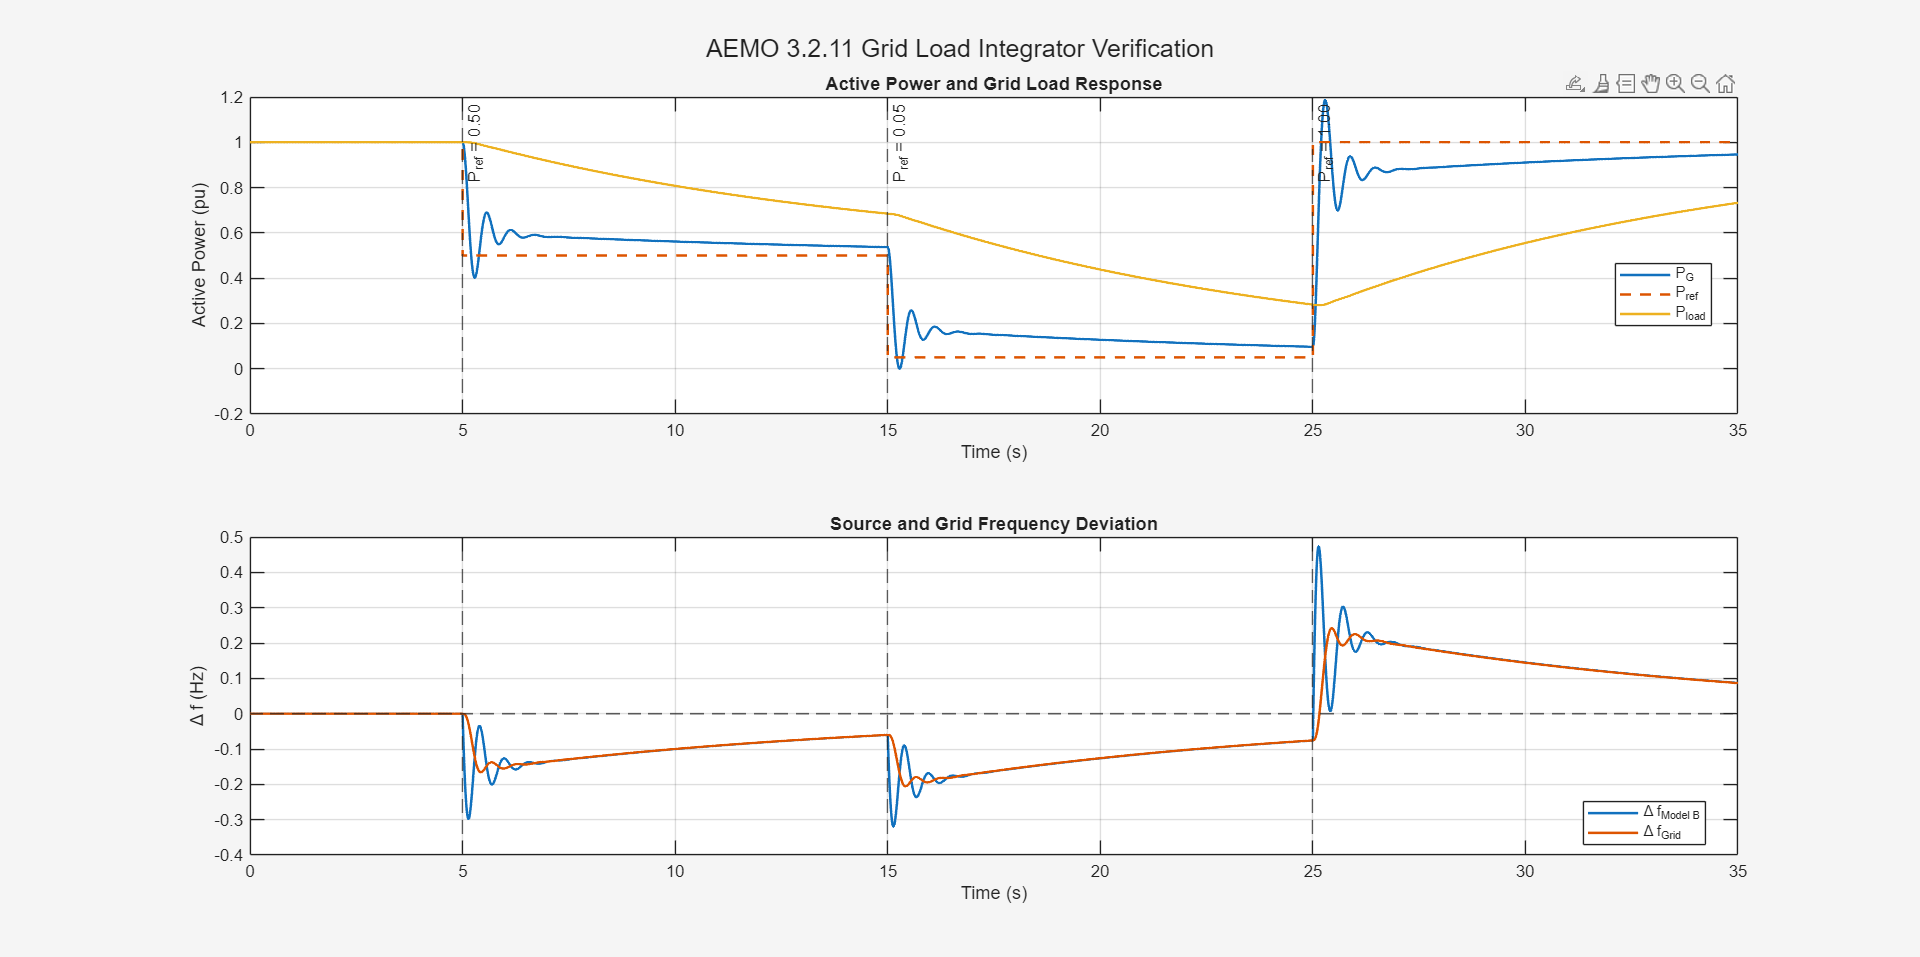



%% ============================================================
% GRID LOAD INTEGRATOR VERIFICATION
% ============================================================

figure('Visible','on');


%% Active Power and Grid Load

subplot(2,1,1);

plot(t,PG,'LineWidth',1.5);
hold on;

plot(t,Pref_plot,'--','LineWidth',1.5);
plot(t,Pload,'LineWidth',1.5);

xline(Pref_t1,'--','P_{ref} = 0.50');
xline(Pref_t2,'--','P_{ref} = 0.05');
xline(Pref_t3,'--','P_{ref} = 1.00');

xlabel('Time (s)');
ylabel('Active Power (pu)');

legend('P_G','P_{ref}','P_{load}','Location','best');

title('Active Power and Grid Load Response');

grid on;


%% Model B and Grid Frequency

subplot(2,1,2);

plot(t,domega1/(2*pi),'LineWidth',1.5);
hold on;

plot(t,domega2/(2*pi),'LineWidth',1.5);

yline(0,'--','LineWidth',1.0);

xline(Pref_t1,'--');
xline(Pref_t2,'--');
xline(Pref_t3,'--');

xlabel('Time (s)');
ylabel('\Delta f (Hz)');

legend('\Delta f_{Model B}','\Delta f_{Grid}','Location','best');

title('Source and Grid Frequency Deviation');

grid on;


sgtitle('AEMO 3.2.11 Grid Load Integrator Verification');